- `% - AI - : I've vibe coded these parts.`

- The `mutualinformationx` function was developed by Mike x Cohen.

## Organizing the Data

### Spike

load Nu.mat
load conNU.mat

Cond_spike = condNU;
grp_th_spike = Cond_spike;
grp_th_spike(Cond_spike > 8) = Cond_spike(Cond_spike > 8) - 8;
grp_r_spike = zeros(size(Cond_spike));
grp_r_spike(Cond_spike < 9) = 1;
grp_r_spike(Cond_spike > 8) = 2;

% Finding trial indices of a condition
% trial_indices = find(grp_th == my_angle & grp_r == my_radius);

neurons = struct();

for neuron = 1:25
    for radius = 1:2  
        for angle = 1:8
            
            % Find trial indices
            angle_trials_spk = find(grp_th_spike == angle & grp_r_spike == radius);
            
            % Extract spike data
            spike_data = nu{neuron}(angle_trials_spk, :);
            
            % Store in struct
            neurons(neuron).radius(radius).angle(angle).trials = angle_trials_spk;
            neurons(neuron).radius(radius).angle(angle).spikes = spike_data;
            neurons(neuron).radius(radius).angle(angle).n_trials = length(angle_trials_spk);
            
        end
    end
end

### LFP

load condLFP.mat
load LFP1.mat

grp_th = Cond;
grp_th(Cond > 8) = Cond(Cond > 8) - 8;
grp_r = zeros(size(Cond));
grp_r(Cond < 9) = 1;
grp_r(Cond > 8) = 2;

all_lfp = struct();

for radius = 1:2
    for angle = 1:8

        % Find trial indices
        angle_trials = find(grp_th == angle & grp_r == radius);

        % Extract LFP data
        lfp_data = LFP(angle_trials, :);

        % Store in struct
        all_lfp(radius).angle(angle).trials = angle_trials;
        all_lfp(radius).angle(angle).lfps = lfp_data;
        all_lfp(radius).angle(angle).n_trials = length(angle_trials);

    end
end

## Raster Plot and PTSH

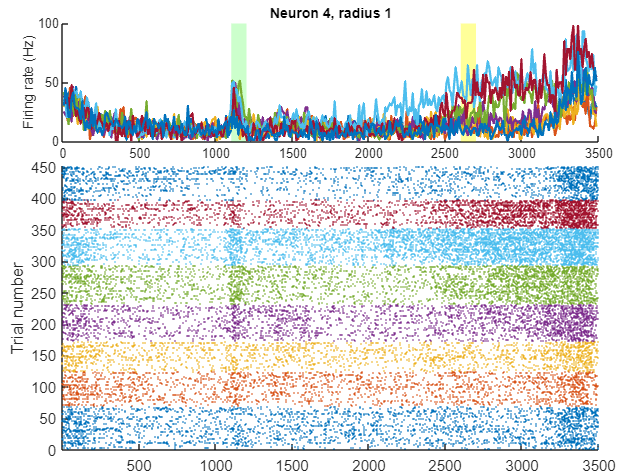

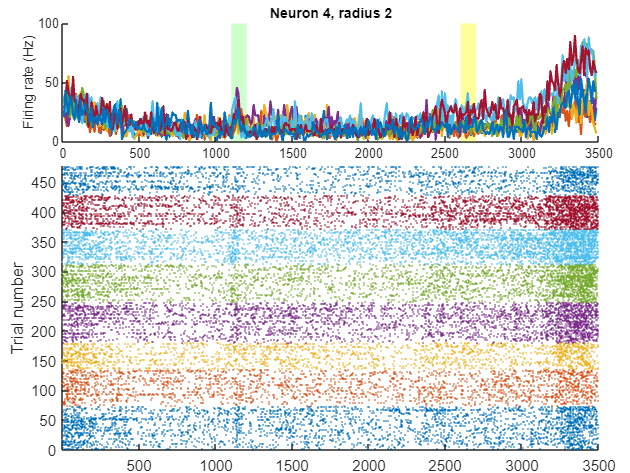

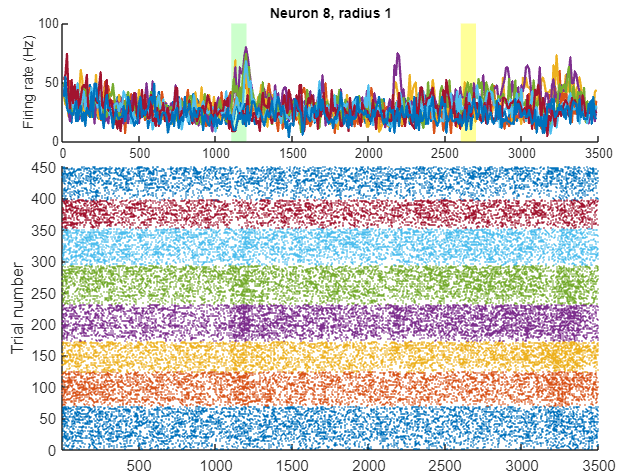

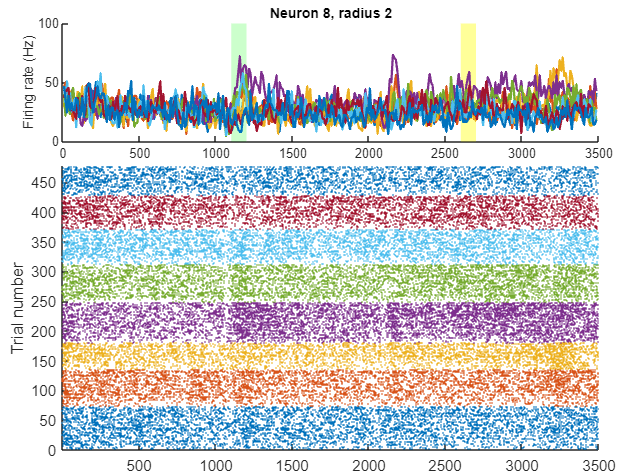

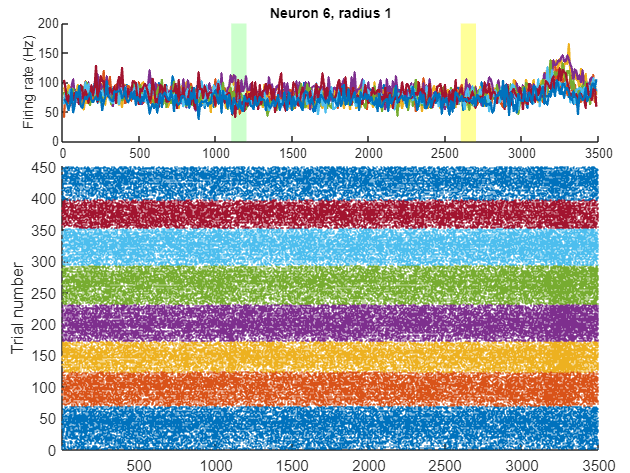

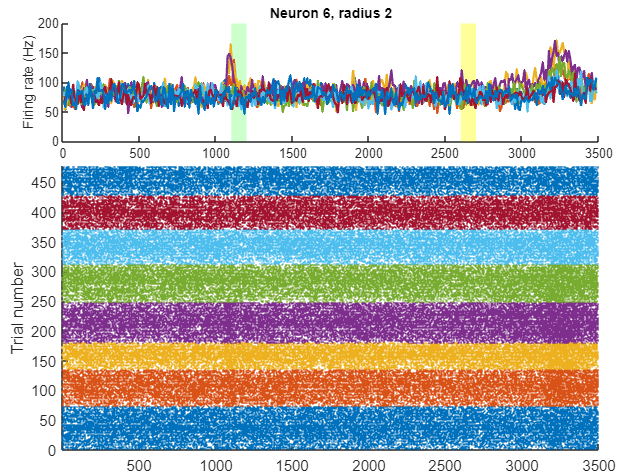

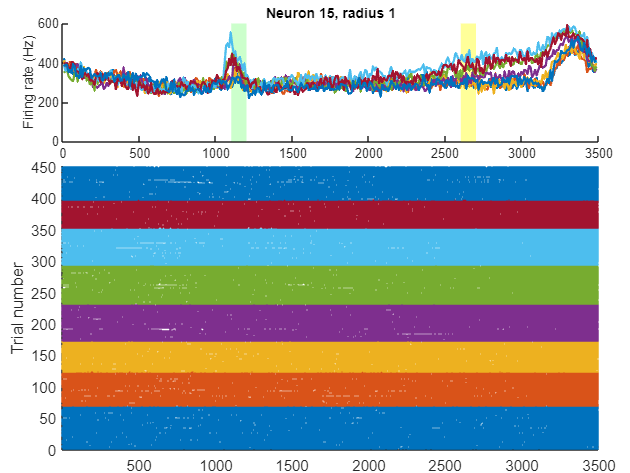

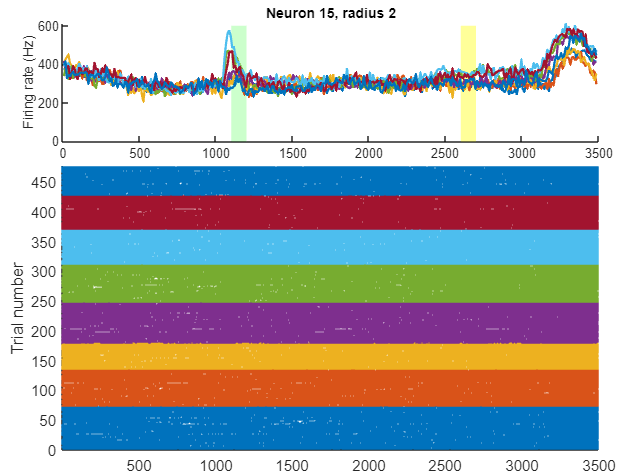

colors = lines(8);

% Neurons to polt
my_neurons = [4, 8, 6, 15];

bin_size = 10;
bins = 1:bin_size:3500;


for n = 1:length(my_neurons)
    neuron = my_neurons(n);
    
    for radius = 1:2
        
        figure;
        
        % ------------------
        % PTSH
        % ------------------

        subplot('Position', [0.1 0.7 0.85 0.25]);
        hold on;

        % Time shades
            if neuron == 15
                mx = 600;
            elseif neuron == 6
                mx = 200;
            else
                mx = 100;
            end
        % encoding
        fill([1100 1200 1200 1100], [0 0 mx mx], 'green', ...
            'FaceAlpha', 0.2, 'EdgeColor', 'none');
        % memory
        fill([2600 2700 2700 2600], [0 0 mx mx], 'yellow', ...
            'FaceAlpha', 0.4, 'EdgeColor', 'none');

        
        for angle = 1:8
            
            angle_data = neurons(neuron).radius(radius).angle(angle).spikes;
            n_trials = neurons(neuron).radius(radius).angle(angle).n_trials;
            
            % - AI -
            spike_counts = zeros(length(bins)-1, 1);
            for bin = 1:length(bins)-1
                bin_start = bins(bin);
                bin_end = bins(bin+1)-1;
                spike_counts(bin) = sum(sum(angle_data(:, bin_start:bin_end)));
            end
            
            % - AI -
            freq = spike_counts / n_trials / (bin_size/1000);
            bins_centers = bins(1:end-1) + bin_size/2;

            plot(bins_centers, freq, 'Color', colors(angle,:), 'LineWidth', 1.5);
        end
        
        ylabel('Firing rate (Hz)');
        title(sprintf('Neuron %d, radius %d', neuron, radius));
        
        % -----------------
        % Raster plot
        % -----------------

        subplot('Position', [0.1 0.05 0.85 0.6]);
        hold on;
        
        trial_counter = 0;
        for angle = 1:8
            
            angle_data = neurons(neuron).radius(radius).angle(angle).spikes;
            n_trials = neurons(neuron).radius(radius).angle(angle).n_trials;
            
            for trial = 1:n_trials
                trial_counter = trial_counter + 1;
                trial_data = angle_data(trial, :);
                spike_times = find(trial_data);
                plot(spike_times, trial_counter * ones(size(spike_times)), ...
                    '.', 'Color', colors(angle,:), 'MarkerSize', 2);
            end

        end
        
        xlim([1 3500]);
        ylim([0 trial_counter+1]);
        xlabel('Time (ms)');
        ylabel('Trial number');
    end
end

## Mutual informatiom

### Mutual information of the time windows

mi_target = zeros(25, 1);
mi_prep = zeros(25, 1);

% Define time windows
win_target = 1000:1500;
win_prep = 2700:3200;

for neuron = 1:25

    rates_target = [];
    rates_prep = [];
    angles_target = [];
    angles_prep = [];
    
    for angle = 1:8

        % Combine both radii
        radi_1 = neurons(neuron).radius(1).angle(angle).spikes;
        radi_2 = neurons(neuron).radius(2).angle(angle).spikes;
        radii = [radi_1; radi_2];
        
        % ----- Target window ----- %
        % Filter the data using the time window
        data_target = radii(:, win_target);
        % Compute firing rate of each trial in that time window
        f_rate_target = sum(data_target, 2) / 0.5;
        % Store the firing rates of this angle
        rates_target = [rates_target; f_rate_target]; % X
        % Store the angles of each firing rate
        angles_target = [angles_target; angle * ones(size(f_rate_target))]; % Y
        
        % ----- Preparation window ----- %
        % Repeat it for eye preparation time window
        data_prep = radii(:, win_prep);
        f_rate_prep = sum(data_prep, 2) / 0.5;
        rates_prep = [rates_prep; f_rate_prep]; % X
        angles_prep = [angles_prep; angle * ones(size(f_rate_prep))]; % Y
    end
    
    % Compute MI for both windows
    mi_target(neuron) = mutualinformationx(rates_target, angles_target);
    mi_prep(neuron) = mutualinformationx(rates_prep, angles_prep);
end

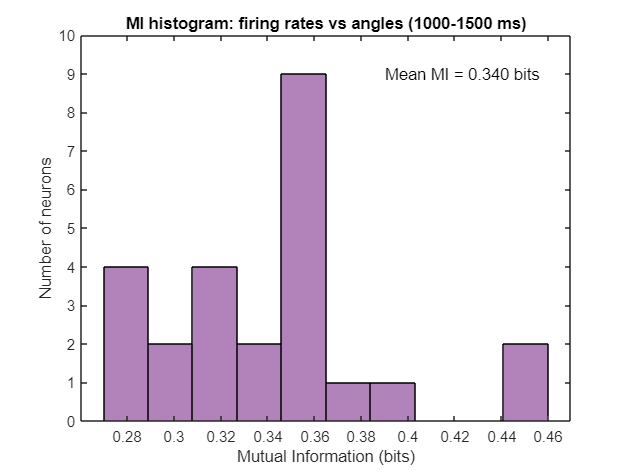

% Histogram for target window
figure;

histogram(mi_target, 10, FaceColor=colors(4, :));

xlabel('Mutual Information (bits)');
ylabel('Number of neurons');
title(sprintf("MI histogram: firing rates vs angles (1000-1500 ms)"));
ylim([0 10]);

text(0.39, 9, sprintf('Mean MI = %.3f bits', mean(mi_target)), 'FontSize', 11);

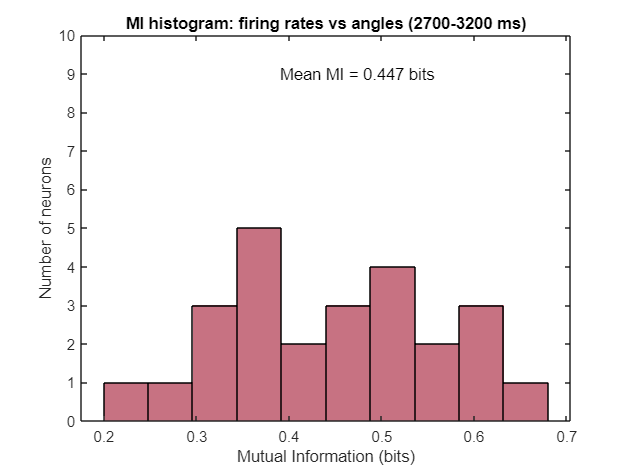

% Histogram for preparation window
figure;

histogram(mi_prep, 10, FaceColor= colors(7, :));

xlabel('Mutual Information (bits)');
ylabel('Number of neurons');
title(sprintf("MI histogram: firing rates vs angles (2700-3200 ms)"));
ylim([0 10]);

% Mean text
text(0.39, 9, sprintf('Mean MI = %.3f bits', mean(mi_prep)), 'FontSize', 11);

### Correlation

% See if data are normally distributed
[h_normal_x, p_normal_x] = lillietest(mi_target);
[h_normal_y, p_normal_y] = lillietest(mi_prep);


% If yes use Pearson r, otherwise Spearman r
if p_normal_x > 0.05 && p_normal_y > 0.05
    corr_type = "pearson";
else
    corr_type = "spearman";
end

% Compute the correlation coefficient
[r, p] = corr(mi_target, mi_prep, 'Type', corr_type);

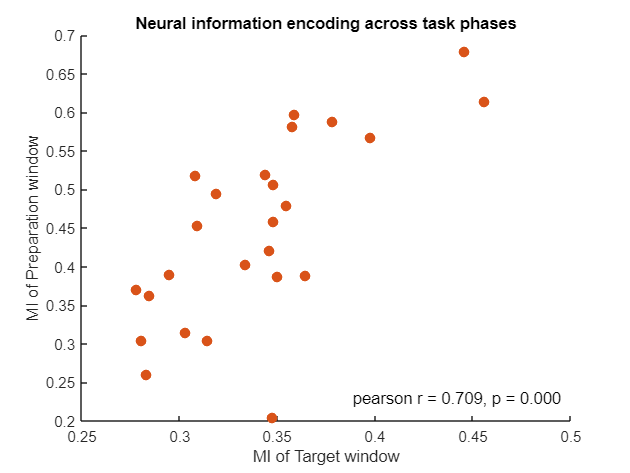

% Scatter plot
figure;
scatter(mi_target, mi_prep, 50, 'filled', MarkerFaceColor= colors(2, :));

xlabel('MI of Target window');
ylabel('MI of Preparation window');
title('Neural information encoding across task phases');

% The r and p-value text
text(0.495, 0.23, ...
    sprintf('%s r = %.3f, p = %.3f', corr_type, r, p), ...
    'FontSize', 11, 'HorizontalAlignment', 'right')

hold off;

## Area Under Curve

### AUC of time windows

auc_target = zeros(25,1);
auc_prep = zeros(25,1);

for neuron = 1:25

    auc_rates = [];
    auc_radii = [];
    auc_rates_prep = [];
    auc_radii_prep = [];

    for radius = 1:2

        for angle = 1:8

            spikes = neurons(neuron).radius(radius).angle(angle).spikes;

            % ----- Target window ----- %
            data_tw = spikes(:, win_target);
            % Firing rate of each trial in that time window
            f_rate = sum(data_tw, 2) / 0.5;

            auc_rates = [auc_rates; f_rate]; % X
            auc_radii = [auc_radii; radius * ones(size(f_rate))]; % Y

            % ----- Prep window ----- %
            data_tw_prep = spikes(:, win_prep);
            f_rate_prep = sum(data_tw_prep, 2) / 0.5;
            auc_rates_prep = [auc_rates_prep; f_rate_prep]; % X
            auc_radii_prep = [auc_radii_prep; radius * ones(size(f_rate_prep))]; % Y
        end

    end

[~, ~, ~, AUC] = perfcurve(auc_radii, auc_rates, 2); % positive = radius 2
auc_target(neuron) = AUC;

[~, ~, ~, AUCp] = perfcurve(auc_radii_prep, auc_rates_prep, 2);
auc_prep(neuron) = AUCp;

end

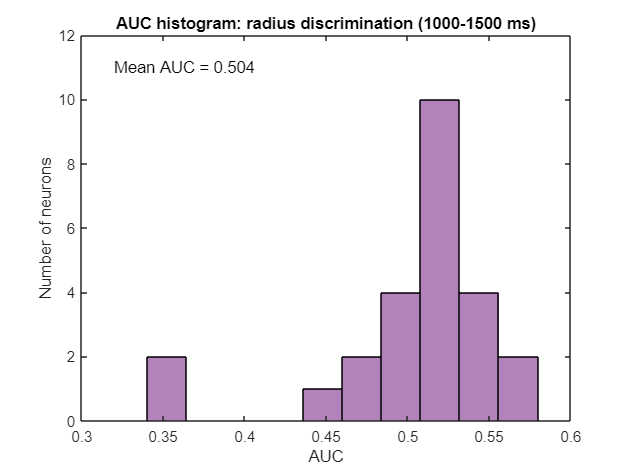

% Histogram for target window AUC
figure;
histogram(auc_target, 10, FaceColor= colors(4, :));

xlabel('AUC');
ylabel('Number of neurons');
title(sprintf("AUC histogram: radius discrimination (1000-1500 ms)"));
xlim([0.3 0.6]);
ylim([0 12]);

% Mean text
text(0.32, 11, sprintf('Mean AUC = %.3f', mean(auc_target)), 'FontSize', 11);

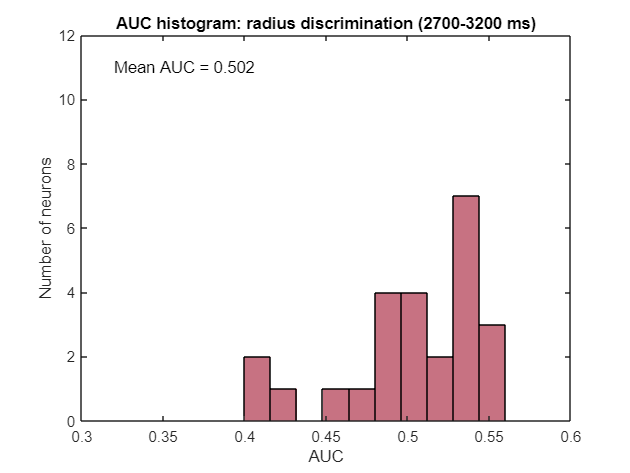

% Histogram for preparation window AUC
figure;
histogram(auc_prep, 10, FaceColor= colors(7, :));

xlabel('AUC');
ylabel('Number of neurons');
title(sprintf("AUC histogram: radius discrimination (2700-3200 ms)"));
xlim([0.3 0.6]);
ylim([0 12]);

text(0.32, 11, sprintf('Mean AUC = %.3f', mean(auc_prep)), 'FontSize', 11);

### Correlation

% Check normality for AUC data
[h_norm_target, p_norm_target] = lillietest(auc_target);

[h_norm_prep, p_norm_prep] = lillietest(auc_prep);

% Choose correlation type
if p_norm_target > 0.05 && p_norm_prep > 0.05
    corr_type_auc = "pearson";
else
    corr_type_auc = "spearman";
end

% Compute correlation
[r_auc, p_auc] = corr(auc_target, auc_prep, 'Type', corr_type_auc);

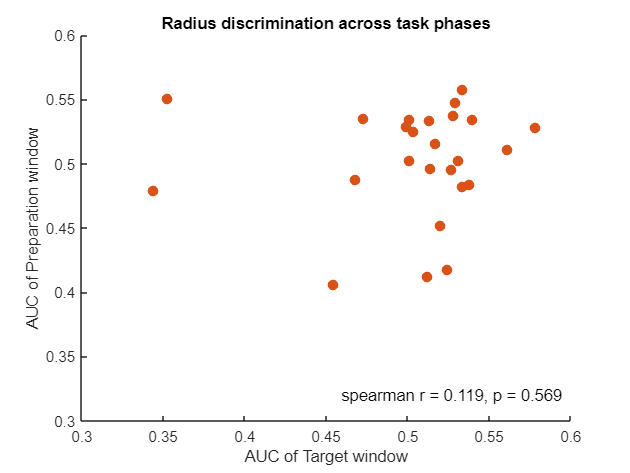

% Scatter plot
figure;
scatter(auc_target, auc_prep, 50, 'filled', MarkerFaceColor= colors(2, :));
xlabel('AUC of Target window');
ylabel('AUC of Preparation window');
title('Radius discrimination across task phases');
xlim([0.3 0.6]);
ylim([0.3 0.6]);

% Add text with correlation
text(0.595, 0.32, ...
    sprintf('%s r = %.3f, p = %.3f', corr_type_auc, r_auc, p_auc), ...
    'FontSize', 11, 'HorizontalAlignment', 'right');

## Angle decoding

### Algorithm

% Feature matrix (X)
ml_data = zeros(928, 25);
for neuron = 1:25
    spikes = nu{neuron};
    f_rate = sum(spikes, 2) / 3.5; % Firing rate of each trial
    ml_data(:, neuron) = f_rate;
end

% Label vector (Y)
ml_label = grp_th_spike;

k = 13;
folds = 20;

% Create cross-validation indices
cv = cvpartition(ml_label, 'KFold', folds);

acc_vector = zeros(folds, 1);

for fold = 1:folds

    % Split the data into training set and test set
    train_idx = cv.training(fold);
    test_idx = cv.test(fold);
    
    % X and Y of those sets
    x_train = ml_data(train_idx, :);
    y_train = ml_label(train_idx);
    x_test = ml_data(test_idx, :);
    y_test = ml_label(test_idx);
    
    % Train kNN model
    model = fitcknn(x_train, y_train, 'NumNeighbors', k, 'Standardize', true);
    
    % Predict using test set
    y_pred = predict(model, x_test);
    
    % Compute accuracy
    acc_vector(fold) = sum(y_pred == y_test) / length(y_test);
end

% Results
mean_acc = mean(acc_vector);
std_acc = std(acc_vector);
ci_95 = 1.96 * (std_acc / sqrt(folds));
chance = 1/8;

fprintf('kNN (k=%d) decoding accuracy: %.2f%% ± %.2f%%\n', ...
    k, mean_acc*100, ci_95*100);

kNN (k=13) decoding accuracy: 39.15% ± 3.96%


fprintf('Chance level: %.1f%%\n', chance*100);

Chance level: 12.5%


### Visualization

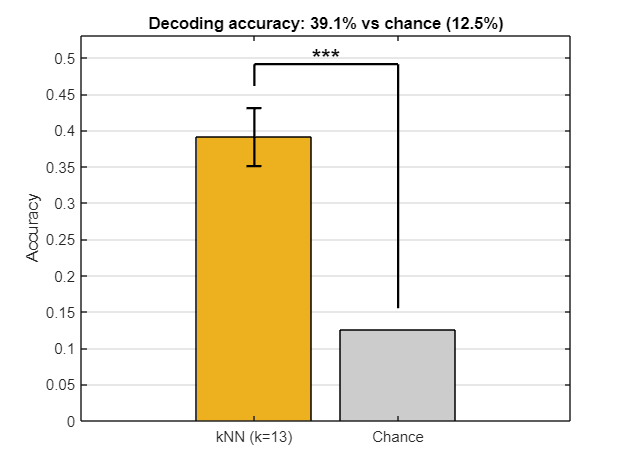

% -AI -
% This cell of code was made by AI. I only adjusted the significance bar coordinates and color.

% One-sample t-test
[h, p, ci, stats] = ttest(acc_vector, chance);

% Plot
figure;
bar_data = [mean_acc, chance];
b = bar(bar_data, 'FaceColor', 'flat');
b.CData(1,:) = colors(3,:);  % kNN color
b.CData(2,:) = [0.8 0.8 0.8];  % chance color
hold on;

errorbar(1, mean_acc, ci_95, 'k', 'LineWidth', 1.5, 'CapSize', 10);

set(gca, 'XTickLabel', {sprintf('kNN (k=%d)', k), 'Chance'}, 'XGrid', 'off', 'YGrid', 'on');
ylabel('Accuracy');
title(sprintf('Decoding accuracy: %.1f%% vs chance (12.5%%)', mean_acc*100));
ylim([0 max(mean_acc+ci_95+0.1, 0.3)]);

% Significance bar
if p < 0.001
    star = '***';
elseif p < 0.01
    star = '**';
elseif p < 0.05
    star = '*';
else
    star = 'ns';
end

% Define Y-positions for vertical drops
fixed = 0.03;
y_knn_top = mean_acc + ci_95 + fixed;  % above kNN error bar
y_chance_top = chance + fixed;          % above chance bar
y_line = max(y_knn_top, y_chance_top) + fixed;  % Horizontal line

% Draw vertical lines from horizontal line down to the targets
plot([1, 1], [y_knn_top, y_line], 'k-', 'LineWidth', 1.5);
plot([2, 2], [y_chance_top, y_line], 'k-', 'LineWidth', 1.5);

% Draw horizontal line
plot([1, 2], [y_line, y_line], 'k-', 'LineWidth', 1.5);

% Add stars
text(1.5, y_line + 0.01, star, ...
    'FontSize', 16, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');

hold off;

## Power Spectrum using Multitapers

s_rate = 1000;
win_length = 500;
nw = 4;

angle_power_target = zeros(win_length/2+1, 8);
angle_power_prep = zeros(win_length/2+1, 8);

for angle = 1:8

    % Get LFP data for both radii
    lfp_data_radi1 = all_lfp(1).angle(angle).lfps;
    lfp_data_radi2 = all_lfp(2).angle(angle).lfps;
    lfp_data = [lfp_data_radi1; lfp_data_radi2];
    n_trials = size(lfp_data, 1);

    for trial = 1:n_trials

        % Target window
        segment = lfp_data(trial, win_target);
        % Remove possible noise
        segment = detrend(segment - mean(segment));
        % Compute power
        [p_target, f_target] = pmtm(segment, nw, win_length, s_rate);
        % Add it up to the previous of trials
        angle_power_target(:, angle) = angle_power_target(:, angle) + p_target;

        % Preparation window
        segment_prep = lfp_data(trial, win_prep);
        segment_prep = detrend(segment_prep - mean(segment_prep));
        [p_prep, f_prep] = pmtm(segment_prep, nw, win_length, s_rate);
        angle_power_prep(:, angle) = angle_power_prep(:, angle) + p_prep;
    end

    % Power average over trials
    angle_power_target(:, angle) = angle_power_target(:, angle) / n_trials;
    angle_power_prep(:, angle) = angle_power_prep(:, angle) / n_trials;

end

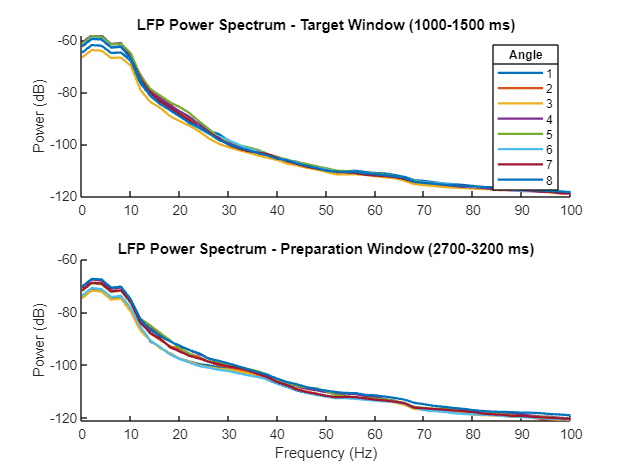

figure;

% Target window
subplot(2,1,1);
hold on;
plot(f_target, 10*log10(angle_power_target), 'LineWidth', 1.5);

xlim([0 100]);
ylabel('Power (dB)');
title('LFP Power Spectrum - Target Window (1000-1500 ms)');

lgd = legend('1', '2', '3', '4', '5', '6', '7', '8');
title(legend, 'Angle');
hold off;

% Preparation window
subplot(2,1,2);
hold on;
plot(f_prep, 10*log10(angle_power_prep), 'LineWidth', 1.5);

xlim([0 100]);
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
title('LFP Power Spectrum - Preparation Window (2700-3200 ms)');
hold off;

## Summary of key results

`% - AI -`

fprintf('MI Target: mean=%.3f, std=%.3f bits\n', mean(mi_target), std(mi_target));

MI Target: mean=0.340, std=0.046 bits


fprintf('MI Prep: mean=%.3f, std=%.3f bits\n', mean(mi_prep), std(mi_prep));

MI Prep: mean=0.447, std=0.121 bits


fprintf('AUC Target: mean=%.3f, std=%.3f\n', mean(auc_target), std(auc_target));

AUC Target: mean=0.504, std=0.054


fprintf('AUC Prep: mean=%.3f, std=%.3f\n', mean(auc_prep), std(auc_prep));

AUC Prep: mean=0.502, std=0.043


fprintf('Decoding accuracy: %.1f%%, CI=[%.1f %% %.1f %%]\n', ...
    mean_acc*100, (mean_acc-ci_95)*100, (mean_acc+ci_95)*100);

Decoding accuracy: 39.1%, CI=[35.2 % 43.1 %]
